close 'all';
clearvars;
clc;

## 1 Generate datasets

M=2; %Number classes
m1=[0; 0];  m2=[1; 2];
m=[m1  m2];
S1=[0.8 0.2;0.2 0.8];
S2=[0.8 0.2;0.2 0.8];
S(:,:,1)=S1;S(:,:,2)=S2;
% A priori probabilities
P1=1/2;  P2=1/2;
P=[P1 P2]';

% Train Data set
N1=1000;
randn('seed',0);
[Xtrain,ytrain]=generate_gauss_classes(m,S,P,N1);
Ntrain_c1=fix(N1*P1); Ntrain_c2=fix(N1*P2); % Cantidad de datos por clase

% Test Data set
N2=500;
randn('seed',100);
[Xtest,ytest]=generate_gauss_classes(m,S,P,N2);
Ntest_c1=fix(N2*P1); Ntest_c2=fix(N2*P2); % Cantidad de datos por clase

## Display Xtrain

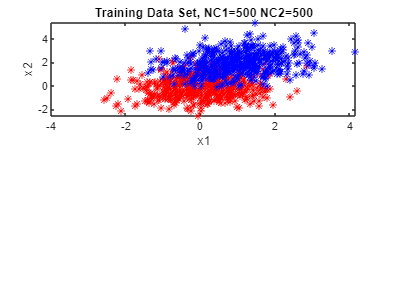

subplot(2,1,1); plot(Xtrain(1,1:Ntrain_c1),Xtrain(2,1:Ntrain_c1),'*r',Xtrain(1,Ntrain_c1+1:Ntrain_c1+Ntrain_c2),Xtrain(2,Ntrain_c1+1:Ntrain_c1+Ntrain_c2),'*b'); 
title(['Training Data Set, NC1=' num2str(Ntrain_c1) ' NC2=' num2str(Ntrain_c2)]); 
 xlabel('x1');ylabel('x2');

## Display Xtest (Prueba)

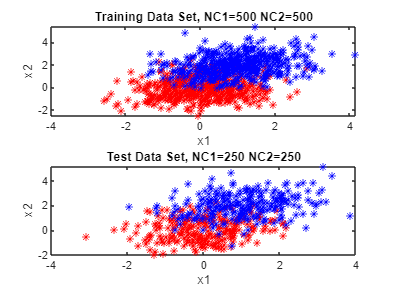

subplot(2,1,2); plot(Xtest(1,1:Ntest_c1),Xtest(2,1:Ntest_c1),'*r',Xtest(1,Ntest_c1+1:Ntest_c1+Ntest_c2),Xtest(2,Ntest_c1+1:Ntest_c1+Ntest_c2),'*b'); 
title(['Test Data Set, NC1=' num2str(Ntest_c1) ' NC2=' num2str(Ntest_c2)]); 
 xlabel('x1');ylabel('x2');

## 2 - Classification Xtest with k_nn_classifier

%knn=3;
knn=5; 
%knn=7;
%knn=11;
AssigClass=k_nn_classifier(Xtrain,ytrain,knn,Xtest);

## 3. Compute the confusion matrix

Index set for plotconfusion Label Tests Data Set 

ind_t1=find(ytest==1);ind_t2=find(ytest==2); 
Targets=zeros(M,N2);
Targets(1,ind_t1)=1; Targets(2,ind_t2)=1;

## Label kNN Classifier

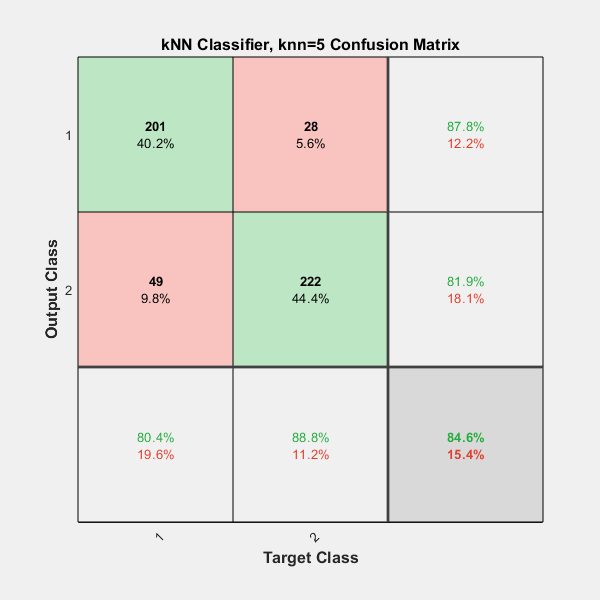

ind_1=find(AssigClass==1); ind_2=find(AssigClass==2); 
Outputs=zeros(M,N2);
Outputs(1,ind_1)=1; Outputs(2,ind_2)=1; 
% Plot Confusion
figure; plotconfusion(Targets,Outputs,['kNN Classifier, knn=' num2str(knn)  ])